# EJERCICIOS ENTREGABLES PRÁCTICA 2-3

### Ejercicio 4 (2,75 puntos). Respuesta transitoria, precisión y error en estado estacionario para sistemas de orden superior. 

Obtenga la respuesta, ante rampa unitaria, de un siguiente sistema de control en lazo cerrado, cuya función de transferencia es: $G\left(s\right)=\frac{s+10}{s^3 +6s^2 +9s+10}$. Realice un análisis analítico y gráfico. ¿Se puede despreciar algún polo (aproximación por polos dominantes) con el fin de reducir el orden del sistema? Con el análisis previo, analice los resultados desde un punto de vista del error y el tipo de sistema. Finalmente, exponga un mismo análisis, pero ahora considerando una entrada exponencial, $r\left(t\right)=e^{-\frac{t}{2}}$ . ¿Qué tipo de respuesta transitoria y estacionaria resulta?

% Definición de la función de transferencia
G = tf([1 10],[1 6 9 10])

G =
 
          s + 10
  ----------------------
  s^3 + 6 s^2 + 9 s + 10
 
Continuous-time transfer function.
Model Properties


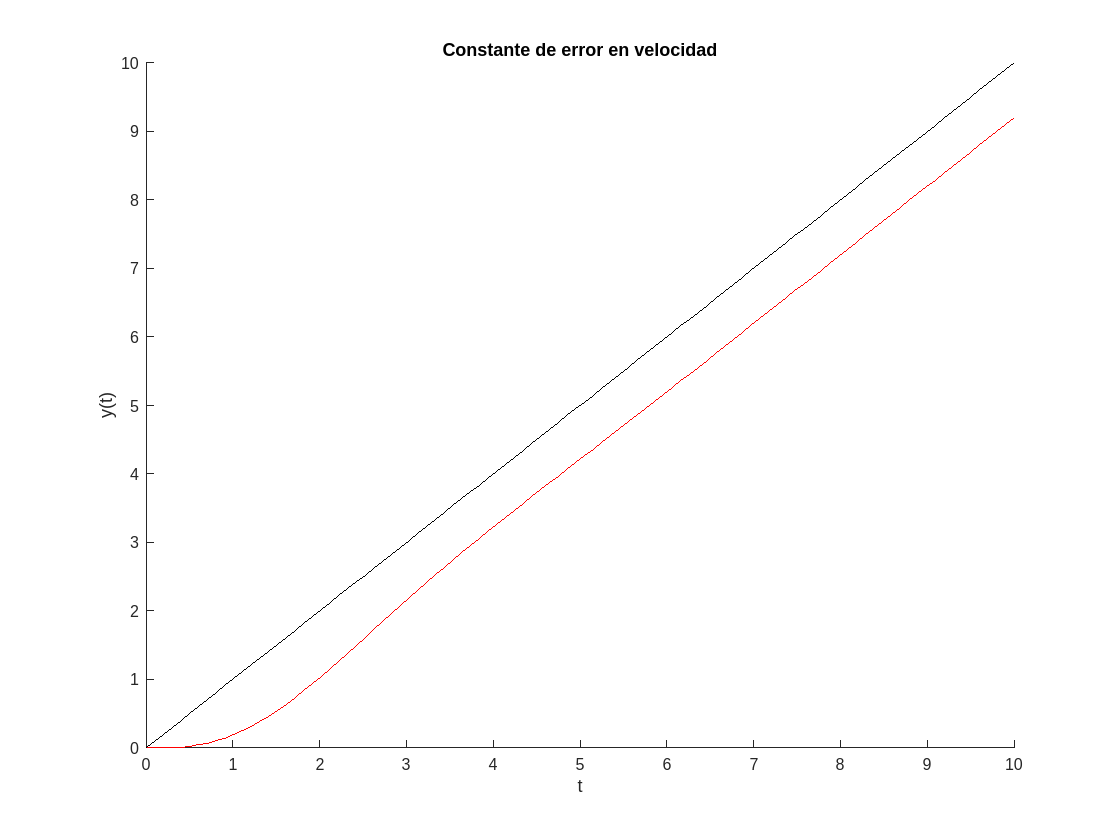


% Respuesta del sistema a una rampa unitaria
t = linspace(0, 10, 100);
rampa = t;
salida_rampa = lsim(G, rampa, t);

figure; hold on;
plot(t, salida_rampa,"-red");
plot(t,t,"-black");
title('Constante de error en velocidad');
ylabel('y(t)');
xlabel('t');
hold off;

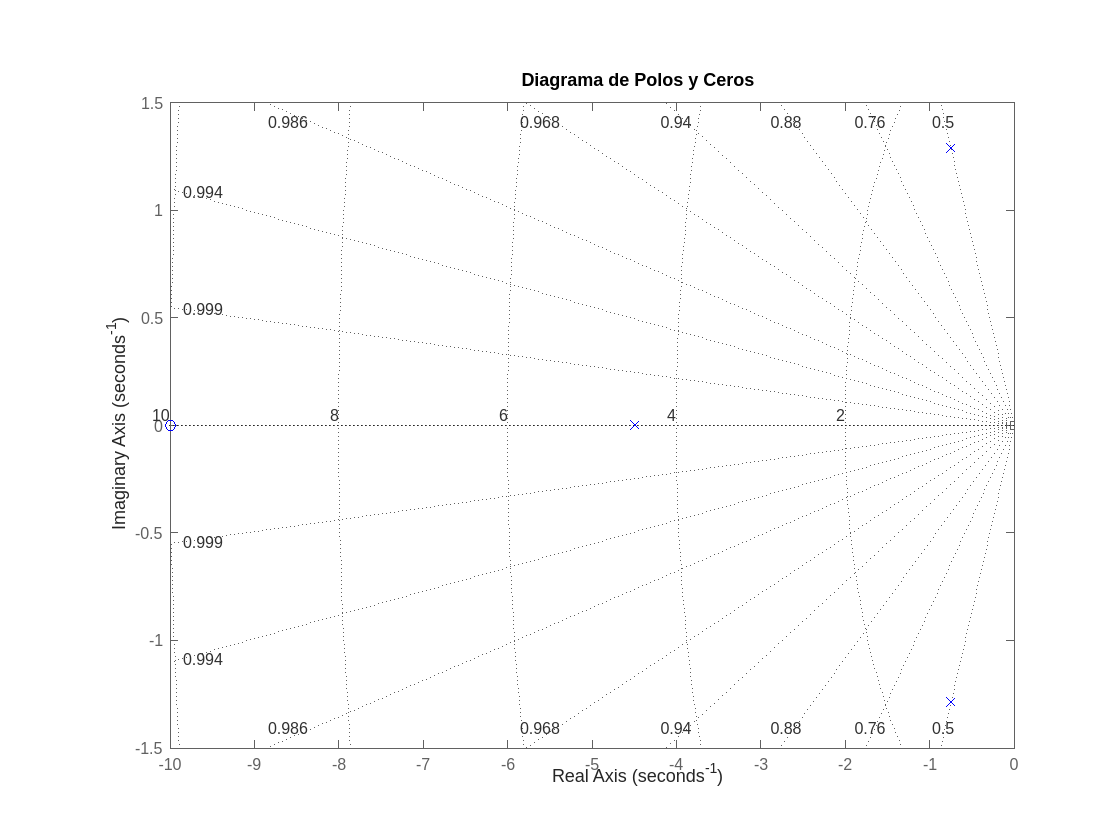


% Análizamos los polos y los ceros del sistema
pzmap(G,"-b");
grid on;
title('Diagrama de Polos y Ceros');

[polos, ceros] = pzmap(G)

polos =   -4.4920 + 0.0000i
  -0.7540 + 1.2875i
  -0.7540 - 1.2875i


ceros = -10

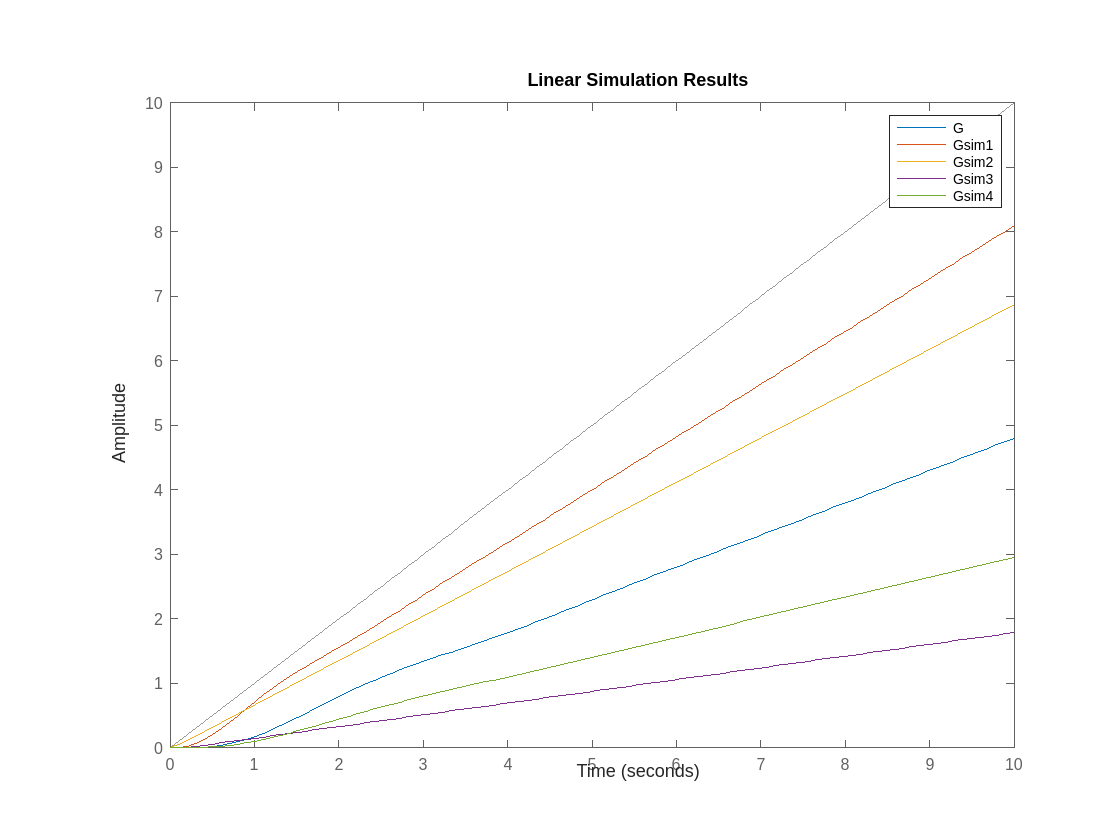


% No se puede despreciar ningun polo como se puede apreciar
Gsim1 = zpk([-10], [-1183/1569+2566/1993i -1183/1569-2566/1993i],1);
Gsim2 = zpk([-10], [-2255/502],1);
Gsim3 = zpk([], [-2255/502],1);
Gsim4 = zpk([], [-1183/1569+2566/1993i -1183/1569-2566/1993i],1);
figure; hold on;
lsim(feedback(G,1), rampa,t)
lsim(feedback(Gsim1,1), rampa,t)
lsim(feedback(Gsim2,1), rampa,t)
lsim(feedback(Gsim3,1), rampa,t)
lsim(feedback(Gsim4,1), rampa,t)
legend('G','Gsim1','Gsim2','Gsim3','Gsim4');hold off;


% Análisis del error y el tipo de sistema
Kp = limit((s+10)/(s^3+6*s^2+9*s+10), s, 0)

$$Kp = 1$$

Kv = limit(((s+10)/(s^3+6*s^2+9*s+10))*s, s, 0)

$$Kv = 0$$

Ka = limit(((s+10)/(s^3+6*s^2+9*s+10))*s^2, s, 0)

$$Ka = 0$$

% Viendo estos resultados sabemos que el sistema es de tipo 0
error_salto = 1/(1+Kp)

$$error\_salto = \frac{1}{2}$$

error_rampa = Inf

error_rampa = Inf

error_parabola = Inf

error_parabola = Inf

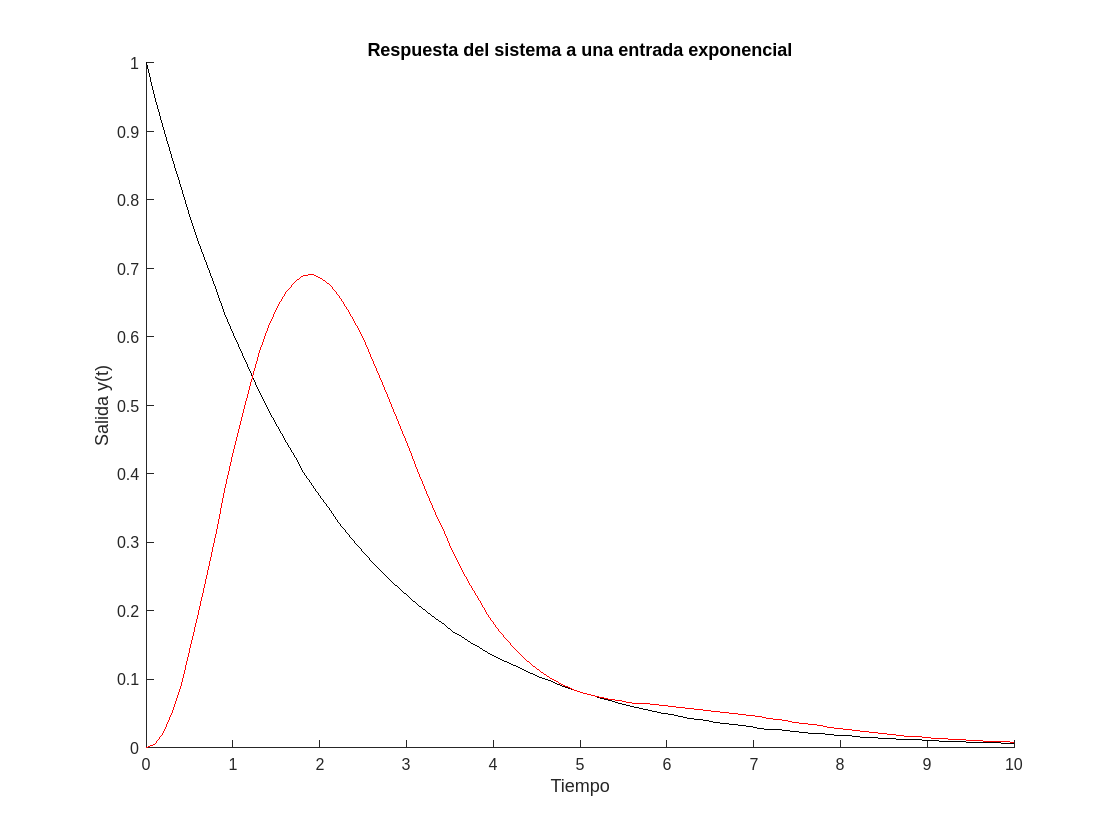



% Respuesta del sistema a una entrada exponencial
exp_input = exp(-t/2);
[y_exp, t_exp] = lsim(G, exp_input, t);

figure;hold on;
plot(t,exp_input,"-black")
plot(t_exp, y_exp,"-red");
title('Respuesta del sistema a una entrada exponencial');
xlabel('Tiempo');
ylabel('Salida y(t)');
hold off;


%Para calcular el error transformamos la exponencial usando laplace
syms t s
R = laplace(exp(-t/2));
G = (s+10)/(s^3+6*s^2+9*s+10);

%Usando la formula general del error calculamos el error que varía con el
%tiempo
E = R/(1+G);